# Método de la rigidez en armaduras

**Título completo:** Aplicación del método de la rigidez a estructuras de tipo armadura

**Autor:** Isacc Alpala

## Contexto

Añadir contexto.

## Requisitos

Añadir requisitos.

## Entradas

Añadir entradas.

clear

nombre_archivo = "aux_armadura_2D.xlsx";
tipo_estructura = "armadura";

## Procedimiento

Añadir procedimiento.

- Importación de datos.

- Determinar la dimensión y número de grados de libertad

- Visualización de la armadura.

- Conversión de unidades.

- Calcular y almacenar la matriz local de cada elemento.

- Calcular la matriz global de la estructura.

- Calcular las reacciones y los desplazamientos.

- Calcular las fuerzas internas.

### 1. Importación de datos

[nodos_tbl, elementos_tbl, desplazamientos_tbl, fuerzas_externas_tbl] = fnc_importar_datos(nombre_archivo);
disp(nodos_tbl)

    Nodo    Coordenada x↵[m]    Coordenada y↵[m]
    ____    _________________    _________________

      1             0                    0        
      2             7                    5        
      3             7                   12        
      4            12                   12        
      5            12                    5        
      6            18                   12        
      7            18                    5        
      8            23                   12        
      9            23                    5        
     10            32                    0        



disp(elementos_tbl)

    Elemento    Nodo inicio    Nodo fin    Área↵[cm2]    Módulo de elasticidad↵[kg/cm2]
    ________    ___________    ________    ___________    _______________________________

        1            1             3           12                     2.1e+06            
        2            1             2           12                     2.1e+06            
        3            2             3           12                     2.1e+06            
        4            2             5           12                     2.1e+06            
        5            3             5           12                     2.1e+06            
        6            3             4           12                     2.1e+06            
        7            5             4           12                     2.1e+06            
        8            

disp(desplazamientos_tbl)

    Nodo    Grado de libertad    Valor↵[cm]
    ____    _________________    ___________

      1             1                  0    
      1             2                  0    
      2             3                NaN    
      2             4                NaN    
      3             5                NaN    
      3             6                NaN    
      4             7                NaN    
      4             8                NaN    
      5             9                  0    
      5            10                  0    
      6            11                NaN    
      6            12                NaN    
      7            13                  0    
      7            14                  0    
      8            15                NaN    
      8            16                NaN    
      9            17                NaN    
      9            18                NaN   

disp(fuerzas_externas_tbl)

    Nodo    Grado de libertad    Valor↵[ton]
    ____    _________________    ____________

      1             1                NaN     
      1             2                NaN     
      2             3                  0     
      2             4                  0     
      3             5                 10     
      3             6                -15     
      4             7                  0     
      4             8                -40     
      5             9                NaN     
      5            10                NaN     
      6            11                  0     
      6            12                  0     
      7            13                NaN     
      7            14                NaN     
      8            15                100     
      8            16                  0     
      9            17                  0     
      9            18   

### 2. Visualización de la armadura

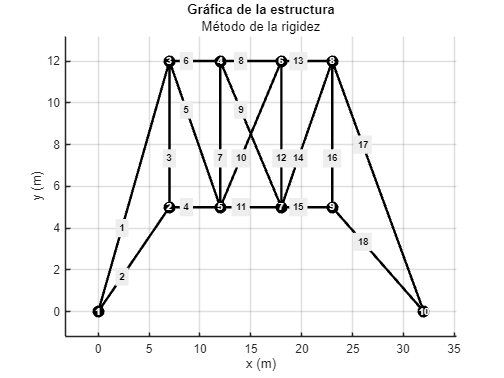

fnc_graficar_estructura(nodos_tbl, elementos_tbl)

ax = gca;

### 3. Conversión de unidades

Dado que la información de las tablas debe ser coherente entre sí y sus unidades para los cálculos posteriores, se realizará las conversiones de unidades necesarias.

[nodos_tbl, fuerzas_externas_tbl] = fnc_convertir_unidades(nodos_tbl, fuerzas_externas_tbl);

### 4. Calcular y almacenar la matriz local de cada elemento

k_local = fnc_matriz_local_armadura2D(nodos_tbl, elementos_tbl);

### 5. Calcular la matriz global de la estructura

k_global = fnc_matriz_global(k_local, tipo_estructura, elementos_tbl, nodos_tbl);

### 6. Calcular las reacciones y los desplazamientos

Para determinar las reacciones (fuerzas desconocidas) y desplazamientos (nodos no restringidos) se debe resolver dos sistemas de ecuaciones lineales detallados a continuación, los cuales surjen a partir de la ecuación de rigidez de la estructura.


$$\mathbf{Q} = \mathbf{K} \mathbf{D}$$


Y mediante particiones se tiene el sistema matricial:


$$\left[ \matrix{\mathbf{Q_k} \cr \mathbf{Q_u}} \right] = \left[ \matrix{\mathbf{K_{11}} & \mathbf{K_{12}} \cr \mathbf{K_{21}} & \mathbf{K_{22}}} \right] \left[ \matrix{\mathbf{D_u} \cr \mathbf{D_k}} \right]$$


El cual se puede desglosar en dos ecuaciones matriciales que sirven para determinar los desplazamientos y las reacciones de toda la estructura.

#### Sistemas de ecuaciones lineales para los desplazamientos

Para determinar los desplazamientos (en nodos no restringidos) se analiza de la siguiente manera:


$$\mathbf{Q_k} = \mathbf{K_{11}}\mathbf{D_u} + \mathbf{K_{12}}\mathbf{D_k} \\
\mathbf{K_{11}}\mathbf{D_u} = \mathbf{Q_k} - \mathbf{K_{12}}\mathbf{D_k}$$


Entonces se podría entender que


$$\mathbf{K_{11}}\mathbf{D_u} = \mathbf{Q_k} - \mathbf{K_{12}}\mathbf{D_k} \\
\mathbf{A}\mathbf{x} = \mathbf{b}$$


Donde $\mathbf{A} = \mathbf{K_{11}}$ y $\mathbf{b} = \mathbf{Q_k} - \mathbf{K_{12}} \mathbf{D_k}$, por lo tanto, aplicando operaciones matriciales se obtiene directamente los desplazamientos de la estructura $\mathbf{x} = \mathbf{D_u}$.

#### Sistema de ecuaciones lineales para las reacciones

Para determinar las reacciones (fuerzas desconocidas) se analiza de la siguiente manera:


$$\mathbf{Q_u} = \mathbf{K_{21}}\mathbf{D_u} + \mathbf{K_{22}}\mathbf{D_k} \\
\mathbf{C} = \mathbf{A} + \mathbf{B}$$


Donde $\mathbf{A} = \mathbf{K_{21}}\mathbf{D_u}$ y $\mathbf{B} = \mathbf{K_{22}}\mathbf{D_k}$, por lo tanto, aplicando operaciones matriciales se obtiene directamente las reacciones de la estructura $\mathbf{C} = \mathbf{Q_u}$.

***Los resultados de los desplazamientos y fuerzas externas (reacciones) desconocidas se adjutan a las tablas iniciales de desplazamiento y fuerza externa, complentando los datos que antes no se conocían.***

[desplazamientos_tbl, fuerzas_externas_tbl] = fnc_resolver_sistema(k_global, desplazamientos_tbl, fuerzas_externas_tbl);

### 7. Calcular las fuerzas internas

% % Cálculo de fuerzas internas.
% fuerza_interna = zeros(cantidad_elementos, 1);
% 
% for i = 1:cantidad_elementos
% 
%     x = [elementos_tbl.xf(i) elementos_tbl.xi(i)];
%     y = [elementos_tbl.yf(i) elementos_tbl.yi(i)];
%     A = elementos_tbl.A(i);
%     E = elementos_tbl.E(i);
% 
%     % Cosenos directores del elemento i-ésimo.
%     L = hypot(x(2) - x(1), y(2) - y(1));
%     dx = abs((x(2) - x(1))) / L;
%     dy = abs((y(2) - y(1))) / L;
% 
%     % Fuerza interna del elemento i-ésimo.
%     idx = fnc_obtener_indices(i, elementos_tbl, dimension, ngl, cantidad_nodos);
%     qF = A*E/L * [-dx -dy dx dy] * desplazamientos_tbl.Value(idx);
% 
%     % Almacenamiento de la fuerza interna i-ésima.
%     fuerza_interna(i) = qF;
% 
% end
% 
% % Visualización de resultados.
% Unit = desplazamientos_tbl.Unit(1);
% Unit = categorical(repelem(Unit, cantidad_elementos, 1));
% Element = (1:cantidad_elementos)';
% InnerForceTbl = table(Element, fuerza_interna, Unit);
% disp(InnerForceTbl)

## Resultados

Añadir resultados.

nodos_tbl(:, 2:3) = nodos_tbl(:, 2:3) ./ 100;
fnc_graficar_estructura(nodos_tbl, elementos_tbl)

disp(desplazamientos_tbl)

    Nodo    Grado de libertad    Valor↵[cm]
    ____    _________________    ___________

      1             1                    0  
      1             2                    0  
      2             3              0.76731  
      2             4              -3.8654  
      3             5               7.5946  
      3             6              -4.6327  
      4             7               7.5822  
      4             8              -2.7514  
      5             9                    0  
      5            10                    0  
      6            11               8.7724  
      6            12              -2.2891  
      7            13                    0  
      7            14                    0  
      8            15               11.166  
      8            16              -9.0633  
      9            17               1.4819  
      9            18              -9.8552 

disp(fuerzas_externas_tbl)

    Nodo    Grado de libertad    Valor↵[kg]
    ____    _________________    ___________

      1             1                  40271
      1             2                  30364
      2             3                      0
      2             4                      0
      3             5                  10000
      3             6                 -15000
      4             7                      0
      4             8                 -40000
      5             9            -1.2028e+05
      5            10                 1277.5
      6            11                      0
      6            12                      0
      7            13            -1.1023e+05
      7            14                  44458
      8            15                  1e+05
      8            16                      0
      9            17                      0
      9            18                 -7000

## Referencias

- *Documentation - MATLAB & Simulink*. (s. f.). [https://www.mathworks.com/help/](https://www.mathworks.com/help/)

- Hibbeler, R. C. (2023). *ANALISIS ESTRUCTURAL* (8.a ed.). PRENTICE HALL/PEARSON.